# Problem Set 3: Clustering

**Submission: **submit a single PDF file to Canvas

**Due: **2/23/2022

**Questions: **Please post all questions to Piazza

**Name:**

**Collaborators:**

This problem set is to familiarize yourself with MATLAB, the Singular Value Decomposition (SVD), and working with real data. You are encouraged to collaborate on the problem sets, but you must include the names and uniqnames of anyone you work with in your submission. The starter code is intended to provide a baseline introduction to the material, and you are encouraged to write additional code to explore the concepts. Please include any plots generated with the code in your written solutions.

**References:**

- [Mathematical Writing: A Primer](https://drive.google.com/file/d/1n-7fnTi3rEKX61jKllVVrBg-snrFhp3E/view?ts=63214e3b)

- [MATLAB Basic Functions Reference](https://www.google.com/url?q=https%3A%2F%2Fwww.mathworks.com%2Fcontent%2Fdam%2Fmathworks%2Ffact-sheet%2Fmatlab-basic-functions-reference.pdf&sa=D&sntz=1&usg=AOvVaw0Srty3yRZ16keZTPoYGuFB)

- [MATLAB Tutorial](https://drive.google.com/file/d/1VcDPSiITW-7hRah3xPNwIBXSnmkcp17w/view?usp=sharing)

## K-Means Clustering

Implement the k*-*means clustering algorithm in the file myKMeans. Once implemented, load the Fisher Iris dataset in the space below and apply the k-Means algorithm to the data.

**Implement myKMeans**

In the file `myKMeans.m`, implement the *K-*means clustering algorithm to cluster a data matrix D into k clusters. Please include a copy of your implementation contained in `myKMeans.m `within your submission. Once implemented, fill in the TODO statements in the code below, run the code, and answer the below questions:

**Solutions:**

**    (a)**

**    (b)**

**    (c)**

**    (d)**

**Load Data**

% Load data
load fisheriris; D = meas;
vars = ["Petal Lengths (cm)", "Petal Width (cm)", "Sepal Lengths (cm)", "Sepal Width (cm)"];

**Visualize the Data**

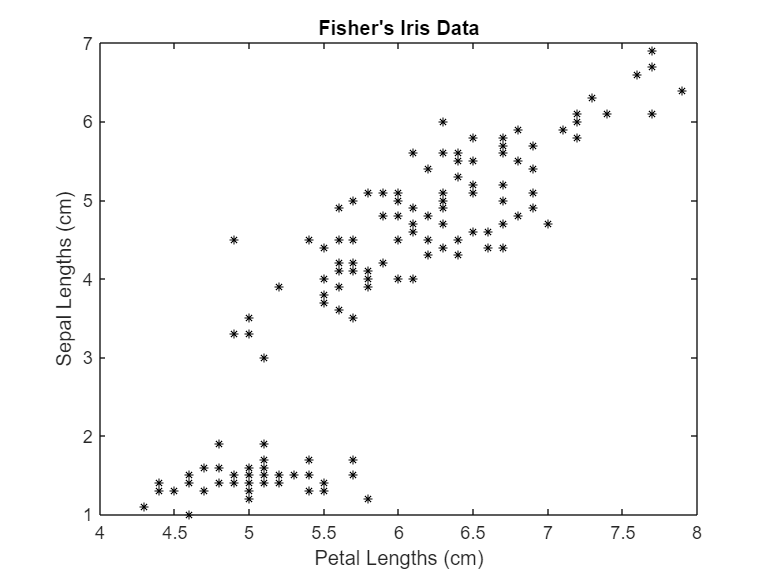

%TODO: set variables to plot in data visuailzation
var1 = 1;
var2 = 3;

plot(D(:,var1),D(:,var2),'k*','MarkerSize',5);
title('Fisher''s Iris Data');
xlabel(vars(var1)); ylabel(vars(var2));

**Apply *****K-*****Means Clustering to the Data**

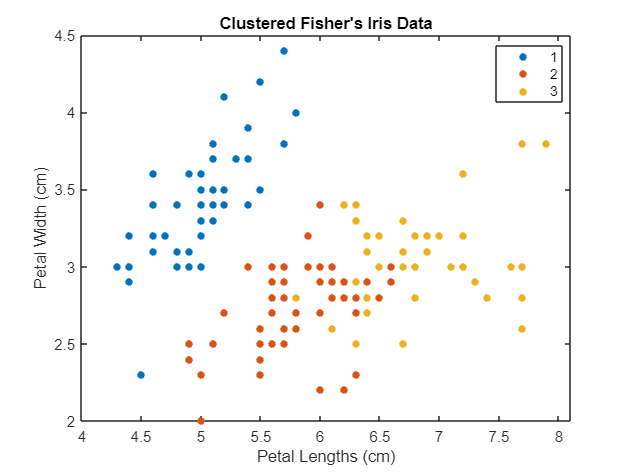

% TODO: select the correct k value
k = 3;

% Apply k-means algorithm
clusters = soln_myKMeans(D,k, 10);

%TODO: set variables to plot in data visuailzation
var1 = 1;
var2 = 2;

% Visulize clusters
gscatter(D(:,var1),D(:,var2), clusters)
title('Clustered Fisher''s Iris Data');
xlabel(vars(var1)); ylabel(vars(var2));

## Spectral Clustering

Three variations of spectral clustering algorithms are described in [A tutorial on spectral clustering](https://drive.google.com/file/d/1Jq9MBRMxDfgnnSZmeVtrYvOb2-vksEIS/view) (page 399). The first algorithm is what Luxburg refers to as ``Unnormalized spectral clustering", the second is ``Normalized spectral clustering" according to Shi and Malik, and the third is ``Normalized spectral clustering" according to Ng et. al. The version of algorithm 3 shown below is an adapted form of Andrew Ng's normalized spectral clustering algorithm described in [On spectral clustering:  Analysis and an algorithm](https://drive.google.com/file/d/1M1zqAHw3317xZd8qNYcRhioyHnmnvIbh/view), which may be helpful for your understanding.

Each of the three algorithms has been implemented in the MATLAB starter code. In this question, each of the three versions of spectral clustering are applied to the same data set in order to compare the quality and computational performance of each algorithm.

**Data:** The matlab variable `data_mat` a 777 x 777 weighted adjacency matrix derived from Hi-C data. To ensure the matrix is connected, rows and columns where more than 10% of the entries were zeros were removed from the matrix. See figures 1 and 2 in the `.pdf` document for examples of how the data and clusters are visualized for this question.

Run the below code and answer the questions in the `.pdf` document.

**Solutions:**

**    (a)**

**    (b)**

**    (c)**

**    (d)**

**Load Data**

load('data/Q1.mat');
W = data_mat;

% TODO: Set k
k = 3;

**Unnormalized Spectral Clustering**

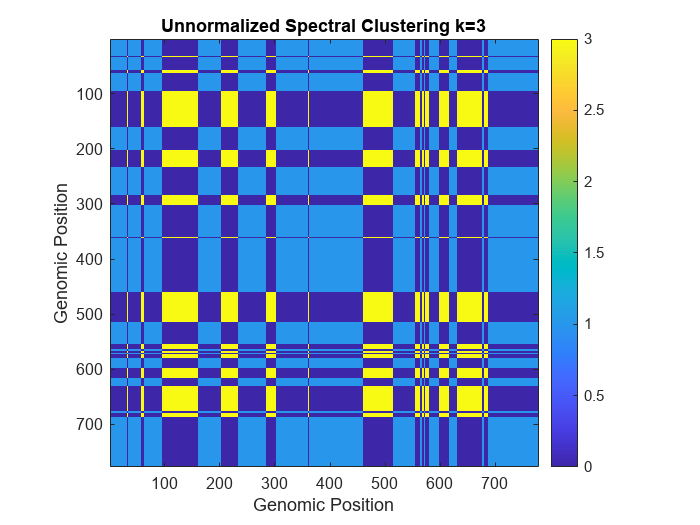

tic;    % Start timer

D = diag(sum(W));   % Degree Matrix
L = D - W;          % Laplacian Matrix
[u, ~] = eig(L);    % Eigendecomposition
uk = u(:, 2:k+1);   % get first k eigenvectors
clusters = kmeans(uk, k);   % Apply K-Means

% assign clusters to the genmoic positions
cluster_plot = zeros(size(clusters));
for cluster_id = 1:max(clusters)
    idx = find(clusters == cluster_id);
    cluster_plot(idx, idx) = cluster_id;
end

alg_1 = toc;    % Get time for Algorithm 1

% Plot the results
figure;
imagesc(cluster_plot);
axis image;
colorbar;
title(sprintf('Unnormalized Spectral Clustering k=%i',k));
xlabel('Genomic Position');
ylabel('Genomic Position');

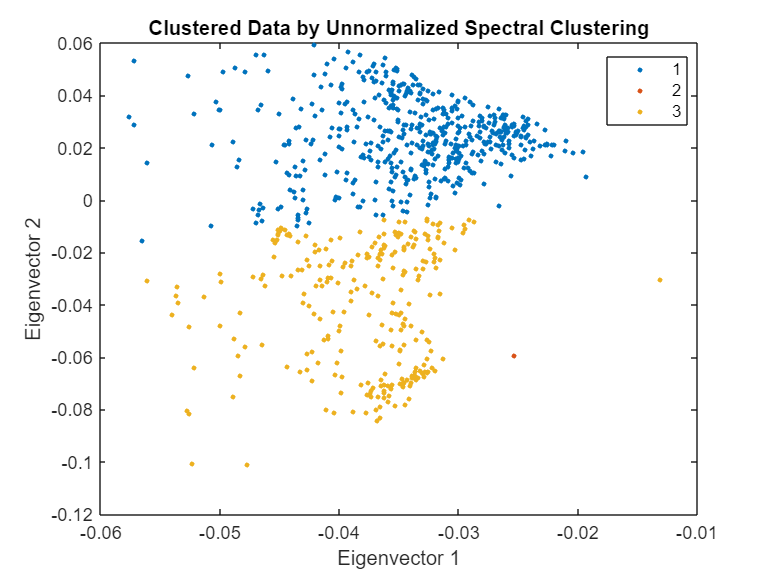

figure;
[U, ~, ~] = svd(W);
gscatter(U(:, 1), U(:, 2), clusters);
title('Clustered Data by Unnormalized Spectral Clustering');
xlabel('Eigenvector 1'); 
ylabel('Eigenvector 2');

**Normalized Spectral Clustering (Shi and Malik)**

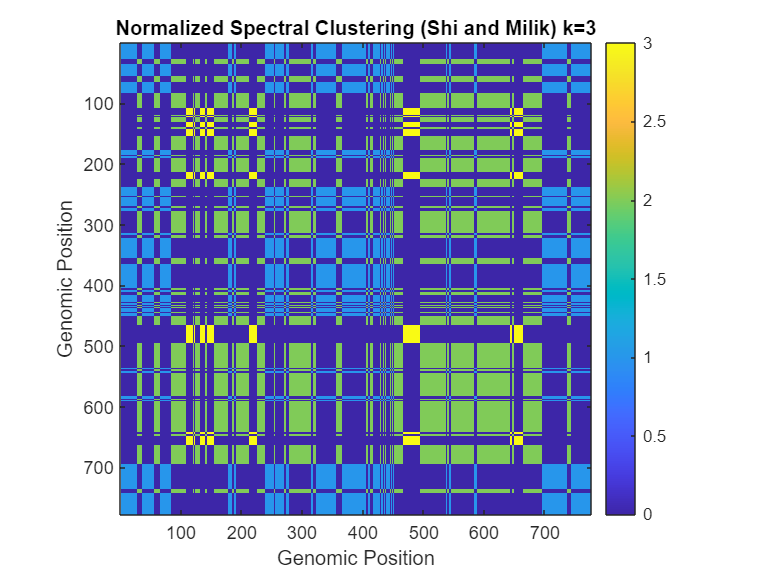

tic;

D = diag(sum(W));   % Degree Matrix
L = D - W;          % Laplacian Matrix
Lrw = D^-1 * L;     % Normalized Laplacian
[u, ~] = eig(Lrw);  % Eigendecomposition
uk = u(:, 2:k+1);   % get first k eigenvectors
clusters = kmeans(uk, k);   % Apply K-Means

% assign clusters to the genmoic positions
cluster_plot = zeros(size(clusters));
for cluster_id = 1:max(clusters)
    idx = find(clusters == cluster_id);
    cluster_plot(idx, idx) = cluster_id;
end

alg_2 = toc;    % Get time for Algorithm 2

imagesc(cluster_plot);
axis image;
colorbar;
title(sprintf('Normalized Spectral Clustering (Shi and Milik) k=%i',k));
xlabel('Genomic Position');
ylabel('Genomic Position');

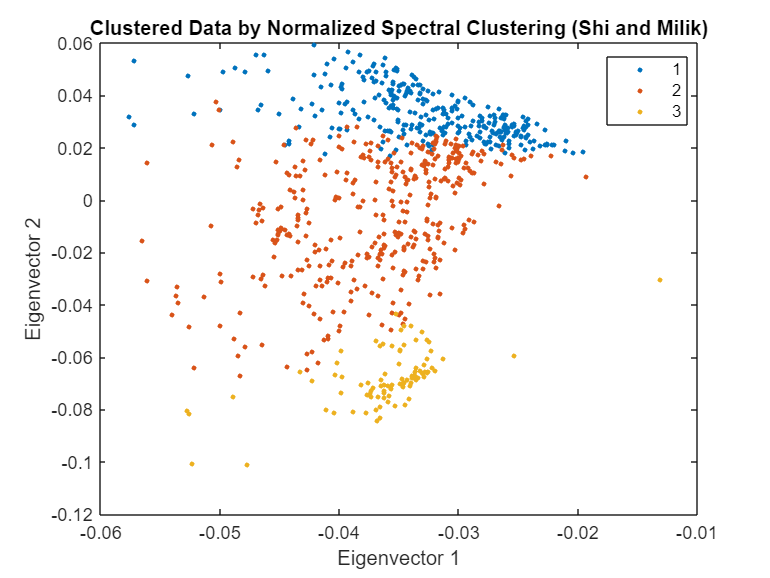

[U, ~, ~] = svd(W);
gscatter(U(:, 1), U(:, 2), clusters);
title('Clustered Data by Normalized Spectral Clustering (Shi and Milik)');
xlabel('Eigenvector 1'); 
ylabel('Eigenvector 2');

**Normalized Spectral Clustering (Ng et al.)**

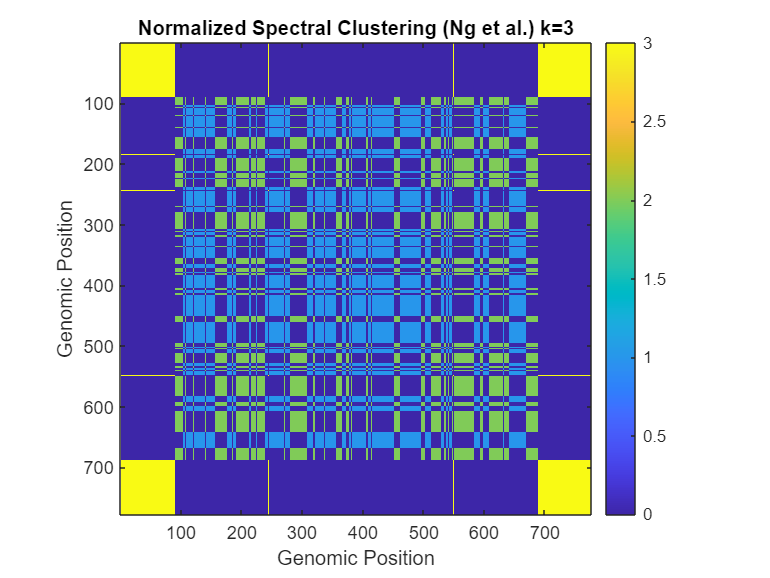

tic;
norm_p = 2; % can be 1 so that rows sum to one
D = diag(sum(W));             % Degree Matrix
L = D - W;                    % Laplacian Matrix
Lsym = D^(-.5) * L * D^(-.5); % normalize the Laplacian
[u, ~] = eig(Lsym);           % Eigendecomposition
uk = u(:, 2:k+1);             % get first k eigenvectors


% normalize the rows of uk using the norm defined by the variable norm_p
% if norm_p = 1, then rows will sum to one
% else if norm_p = 2, they will not
for i = 1:length(uk)
    t(i, :) = abs(uk(i, :) ./ norm(uk(i, :), norm_p));
end

% cluster the normalized rows 
clusters = kmeans(t, k);

% assign clusters to the genmoic positions
cluster_plot = zeros(size(clusters));
for cluster_id = 1:max(clusters)
    idx = find(clusters == cluster_id);
    cluster_plot(idx, idx) = cluster_id;
end

alg_3 = toc;

% plot the sucker
imagesc(cluster_plot);
axis image;
colorbar;
title(sprintf('Normalized Spectral Clustering (Ng et al.) k=%i',k));
xlabel('Genomic Position');
ylabel('Genomic Position');

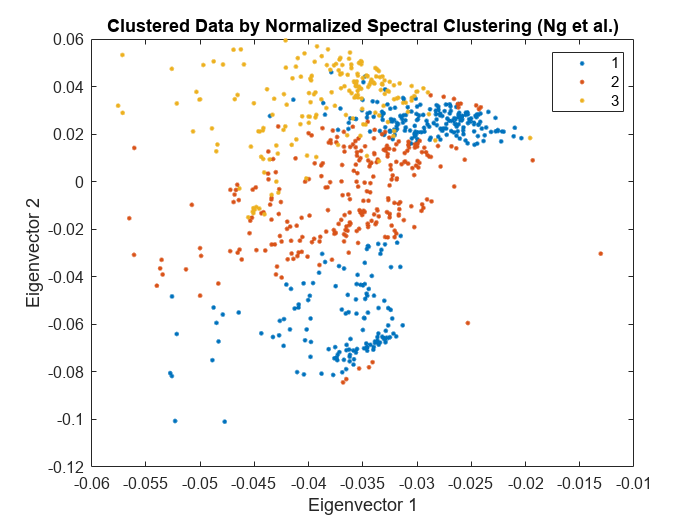


[U, ~, ~] = svd(W);
gscatter(U(:, 1), U(:, 2), clusters);
title('Clustered Data by Normalized Spectral Clustering (Ng et al.)');
xlabel('Eigenvector 1'); 
ylabel('Eigenvector 2');

## New Clustering Algorithm

k−Means is the most fundamental clustering algorithm, and the significance of spectral clustering is motivated by our understanding of the singular values and spectra of the data, but there are an endless number of additional clustering algorithms. For an overview of, see the [scipy clustering library overview page](https://scikit-learn.org/stable/modules/clustering.html). Based on your understanding of data, the clustering algorithms we have seen, and any other resources, propose and implement a new clustering algorithm.

**Data: **Obtain a data set of personal interest to apply your proposed clustering algorithm. The data set should contain a sufficient number of samples ($n\ge 100$) and features per sample. 

Implement your code in the section below, and answer the questions in the `.pdf` document.

**Solutions:**

**    (a):**

**    (b):**

**    (c):**

**    (d):**

**    (e):**

**    (f):**

% TODO: Load your data and implement your clustering here

